clc;
clear all;


%Definição dos parâmetros do Robô RR

a1=20;
a2=10;
a3=5;
alfa=-pi/2;% parâmetro necessário para que a posição zero do robô tenha a configuração desejada na qual o eixo x2 (cotovelo)  está a -90º em relação a x1 (levantamento do braço)

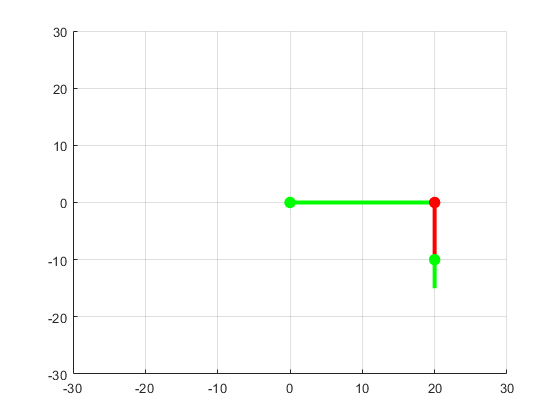

hold on
xlim([-30 30])
ylim([-30 30])
plot([0 a1],[0 0], 'LineWidth', 3, 'Color', 'g');
plot([a1 a1],[0 -a2], 'LineWidth', 3, 'Color', 'r');
plot([a1 a1],[-a2 -a3-a2], 'LineWidth', 3, 'Color', 'g');
scatter(0, 0, 75,'filled','green')
scatter(a1, 0,75,'filled','red')
scatter(a1,- a2,75,'filled',['green'])
grid on
hold off

%Espaço de Trabalho

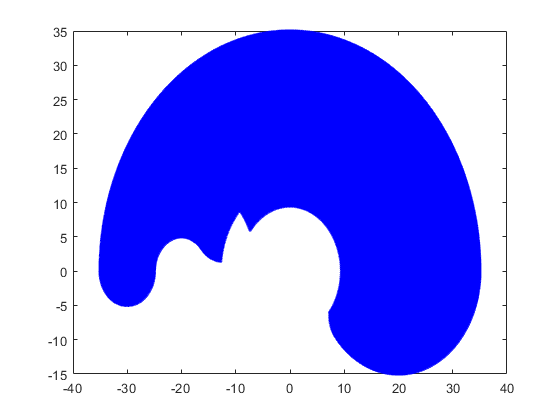

i=0;

theta1_limInf=0;%limite inferior de theta 1 em graus
theta1_limSup=180;%limite superior de theta 1 em graus
theta2_limInf=-50;%limite inferior de theta 2 em graus
theta2_limSup=90;%limite superior de theta 2 em graus
theta3_limInf=-135;%limite inferior de theta 3 em graus
theta3_limSup=135;%limite superior de theta 3 em graus

theta1_limInf=deg2rad(theta1_limInf);
theta1_limSup=deg2rad(theta1_limSup);
theta2_limInf=deg2rad(theta2_limInf);
theta2_limSup=deg2rad(theta2_limSup);
theta3_limInf=deg2rad(theta3_limInf);
theta3_limSup=deg2rad(theta3_limSup);


for theta1=theta1_limInf:(theta1_limSup-theta1_limInf)/100:theta1_limSup,
    for theta2=theta2_limInf:(theta2_limSup-theta2_limInf)/100:theta2_limSup,
        for theta3=theta3_limInf:(theta3_limSup-theta3_limInf)/100:theta3_limSup,
            i=i+1;
            x(i)=a1*cos(theta1)+a2*cos(theta1+theta2+alfa)+a3*cos(theta1+theta2+theta3);%cinemática direta de posição x
            y(i)=a1*sin(theta1)+a2*sin(theta1+theta2+alfa)+a3*sin(theta1+theta2+theta3); %cinemática direta de posição y
        end
     end
end
plot(x,y,'.b');
hold on;

%Definição da Trajetória Retilínea
%TRAJETORIA 1

% p0_r=[16.24, -6,219]
% p1_r=[24.74, 13.57];

%TRAJETORIA 2
p0_r=[2.603, 13.67]

p0_r =     2.6030   13.6700


p1_r=[18.5, 2.991];

Dx=p1_r(1)-p0_r(1); 
Dy=p1_r(2)-p0_r(2);
A=Dy/Dx;
b=p0_r(1,2)-A*p0_r(1,1);
k=0;
n_pontos_r=80;
for i=p0_r(1,1):(p1_r(1,1)-p0_r(1,1))/(n_pontos_r-1):p1_r(1,1),
    k=k+1;
    tx_r(k)=i;
    ty_r(k)=A*tx_r(k)+b ;
end

%Definição do Tempo da Trajetória Retilínea e do Intervalo de Amostragem

Tempo_r=30e-3; % Intervalo de amostragem igual a 40 milissegundos

T_r(1)=0;
for i=2:n_pontos_r,
    T_r(i)=T_r(i-1)+Tempo_r;
end

%Definição dos Intervalos de Tempo da Trajetória Retilínea

dT_r=diff(T_r);

%Controlador Proporcional para Trajetória Retilínea

K_r=[20,0;0,20];

Definido o ponto inicial

xPos = 2.603; %x position of end-effector
yPos = 13.67;%y position of end-effector

P = [xPos yPos]; %end-effector position vector


%Posição Inicial
format compact;
a1 = 20; %link 1 length
a2 = 10; %link 2 length
a3 = 5; 


phi_d = -135

phi_d = -135

phi = deg2rad(phi_d)

phi = -2.3562

Wx = xPos - a3*cos(phi)

Wx = 6.1385

Wy = yPos - a3*sin(phi)

Wy = 17.2055

%Posição Inicial

theta2 =   - acos((Wx^2 + Wy^2 - a1^2 - a2^2)/(2*a1*a2));
theta1 = atan2(Wy,Wx) + acos((Wx^2 + Wy^2 + a1^2 - a2^2)/(2*a1*sqrt(Wx^2+Wy^2)));
theta3 = phi - theta2 - theta1;

theta2_d = rad2deg(theta2)

theta2_d = -114.5647

theta1_d = rad2deg(theta1)

theta1_d = 100.2238

theta3_d = rad2deg(theta3)

theta3_d = -120.6591


alfa = -pi/2;

q_r(:,1) = [theta1;(theta2-alfa);theta3_d]; %joint angle vector


Rotz1 = [cos(theta1) -sin(theta1) 0 0;...
          sin(theta1)  cos(theta1) 0 0;...
          0 0 1 0;...
          0 0 0 1];
Trans1 = [1 0 0 a1;...
           0 1 0 0;...
           0 0 1 0;...
           0 0 0 1];
Rotz2 = [cos(theta2) -sin(theta2) 0 0;...
          sin(theta2)  cos(theta2) 0 0;...
          0 0 1 0;...
          0 0 0 1];
Trans2 = [1 0 0 a2;...
           0 1 0 0;...
           0 0 1 0;...
           0 0 0 1];
       
Rotz3 = [cos(theta3) -sin(theta3) 0 0;...
          sin(theta3)  cos(theta3) 0 0;...
          0 0 1 0;...
          0 0 0 1];
Trans3 = [1 0 0 a3;...
           0 1 0 0;...
           0 0 1 0;...
           0 0 0 1];

T = Rotz1*Trans1*Rotz2*Trans2*Rotz3*Trans3

T =    -0.7071    0.7071         0    2.6030
   -0.7071   -0.7071         0   13.6700
         0         0    1.0000         0
         0         0         0    1.0000


T_01 = Rotz1*Trans1

T_01 =    -0.1775   -0.9841         0   -3.5499
    0.9841   -0.1775         0   19.6824
         0         0    1.0000         0
         0         0         0    1.0000



T_02 = T_01*Rotz2*Trans2

T_02 =     0.9688    0.2477         0    6.1385
   -0.2477    0.9688         0   17.2055
         0         0    1.0000         0
         0         0         0    1.0000



T_03 = T_02*Rotz3*Trans3

T_03 =    -0.7071    0.7071         0    2.6030
   -0.7071   -0.7071         0   13.6700
         0         0    1.0000         0
         0         0         0    1.0000


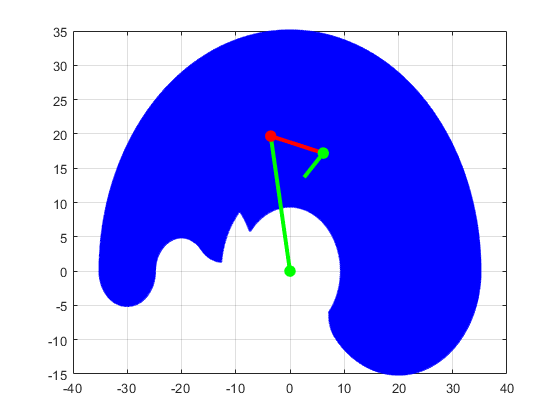


P = [0;0;0;1];
P1 = T_01*P; 
P2 = T_02*P;
P3 = T_03*P;
hold on
plot([0 P1(1)],[0 P1(2)], 'LineWidth', 3, 'Color', 'g');
plot([P1(1) P2(1)],[P1(2) P2(2)], 'LineWidth', 3, 'Color', 'r');
plot([P2(1) P3(1)],[P2(2) P3(2)], 'LineWidth', 3, 'Color', 'g');
scatter(0,0,75,'filled','green')
scatter(P1(1),P1(2),75,'filled','red')
scatter(P2(1),P2(2),75,'filled',['green'])
grid on;


theta1_r= theta1_d;
theta2_r= theta2_d;
theta3_r= theta3_d;



theta1_r=deg2rad(theta1_r);
theta2_r=deg2rad(theta2_r);
theta3_r=deg2rad(theta3_r);

q_r(:,1)=[theta1_r; 
        theta2_r-alfa;
    theta3_r];

%Definição das velocidade desejadas do efetuador para trajetória Retilínea

dtx_r=diff(tx_r);
dty_r=diff(ty_r);


%CONTROLE DE TRAJETÓRIA RETILÍNEA

for i=1:n_pontos_r,
    X_pot_r(:,i)=[a1*cos(q_r(1,i))+a2*cos(q_r(1,i)+q_r(2,i)+alfa)+a3*cos(q_r(1,i)+q_r(2,i)+alfa+q_r(3,i));
                a1*sin(q_r(1,i))+a2*sin(q_r(1,i)+q_r(2,i)+alfa)+a3*sin(q_r(1,i)+q_r(2,i)+alfa+q_r(3,i))]; %posição corrente q_p do efetuador
            
    Xd_r(:,i)=[tx_r(i);
        ty_r(i)]; %posicao desejada (pd ou xd)
    
    e_r(:,i)=Xd_r(:,i)-X_pot_r(:,i); %erro de posição(e_p)
    
    if(i<n_pontos_r)
        
        %velocidade pd_ponto (feedfoward)
        dXd_r(:,i)=[dtx_r(i)./dT_r(:,i); dty_r(i)./dT_r(:,i)];
        
        %lei de controle u_p_barra - velocidade linear do efetuador relativo a contribuição da velocidade das juntas
        u_r(:,i)=K_r*e_r(:,i)+dXd_r(:,i);
        
        
        
        jacob = [(-(a1*sin(q_r(1,i))+a2*sin(q_r(1,i)+q_r(2,i)+alfa)+a3*sin(q_r(1,i)+q_r(2,i)+q_r(3,i)+alfa))), (-((a2*sin(q_r(1,i)+q_r(2,i)+alfa))+(a3*sin(q_r(1,i)+q_r(2,i)+q_r(3,i)+alfa)))), (-a3*sin(q_r(1,i)+q_r(2,i)+q_r(3,i)+alfa));
                       (a1*cos(q_r(1,i))+a2*cos(q_r(1,i)+q_r(2,i)+alfa)+a3*cos(q_r(1,i)+q_r(2,i)+q_r(3,i)+alfa)), ((a2*cos(q_r(1,i)+q_r(2,i)+alfa))+(a3*cos(q_r(1,i)+q_r(2,i)+q_r(3,i)+alfa))), a3*cos(q_r(1,i)+q_r(2,i)+q_r(3,i)+alfa)];
        jacob_transposta = jacob.';  
        pseudoInv_Jacob = jacob_transposta*(inv(jacob*jacob_transposta));
                 
        %velocidade das juntas qp_ponto=up -> inverso do jacobiano * lei de controle (u = (j(q_p)^-1)
        dq_r(:,i)=pseudoInv_Jacob*u_r(:,i);
        
%         %limitando a vel das juntas 80°/s%
%         vel_lim_pos(:,i)=deg2rad(80);%em rad
%         vel_lim_neg(:,i)=deg2rad(-80);%em rad
%                
%         if (dq_r(1,i) < 0)
%             if (abs(dq_r(1,i)) > vel_lim_pos(:,i))
%                 dq_r(1,i) = vel_lim_neg(:,i);
%             end
%         end
%         if (dq_r(1,i) > 0)
%             if (abs(dq_r(1,i)) > vel_lim_pos(:,i))
%                 dq_r(1,i) = vel_lim_pos(:,i);
%             end
%         end
%         
%          if (dq_r(2,i) < 0)
%             if (abs(dq_r(2,i)) > vel_lim_pos(:,i))
%                 dq_r(2,i) = vel_lim_neg(:,i);
%             end
%         end
%         if (dq_r(2,i) > 0)
%             if (abs(dq_r(2,i)) > vel_lim_pos(:,i))
%                 dq_r(2,i) = vel_lim_pos(:,i);
%             end
%         end
               
        
        %posição corrente q_p
        q_r(:,i+1)=q_r(:,i)+dq_r(:,i)*dT_r(:,i);
        
        %limites mecanicos
        if q_r(1,i+1)>theta1_limSup,%Limite Mecânico Medido
           q_r(1,i+1)=theta1_limSup;
        end
        if q_r(1,i+1)<theta1_limInf, %Limite Mecânico Medido
           q_r(1,i+1)=theta1_limInf;
        end
        if q_r(2,i+1)>theta2_limSup, %Limite Mecânico Medido
           q_r(2,i+1)=theta2_limSup;
        end
        if q_r(2,i+1)<theta2_limInf, %Limite Mecânico Medido
           q_r(2,i+1)=theta2_limInf;
        end
        if q_r(3,i+1)>theta3_limSup, %Limite Mecânico Medido
           q_r(3,i+1)=theta3_limSup;
        end
        if q_r(3,i+1)<theta3_limInf, %Limite Mecânico Medido
           q_r(3,i+1)=theta3_limInf;
        end
    end
end

%Gráfico da Trajetória Retilínea juntamente com Espaço de Trabalho

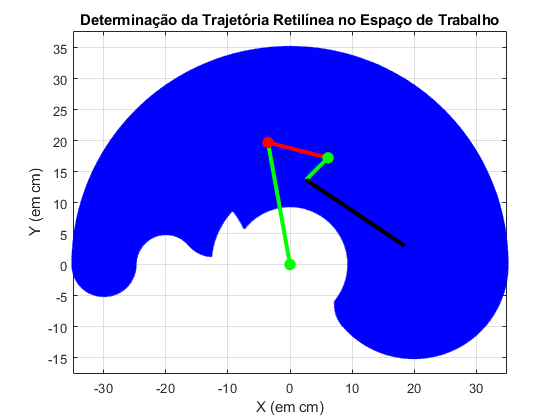

plot(tx_r,ty_r,'k','LineWidth',3);
xlabel('X (em cm)'), ylabel('Y (em cm)'), title('Determinação da Trajetória Retilínea no Espaço de Trabalho');
axis equal;

%Conversão de Radianos para Graus

q_r=rad2deg(q_r); %Variáveis de Juntas para Trajetória Retilínea
dq_r=rad2deg(dq_r); %Velocidades das Juntas para Trajetória Retilínea

%Gráficos Pedidos

%********Trajetória Desejada X Trajetória Efetuada*************************

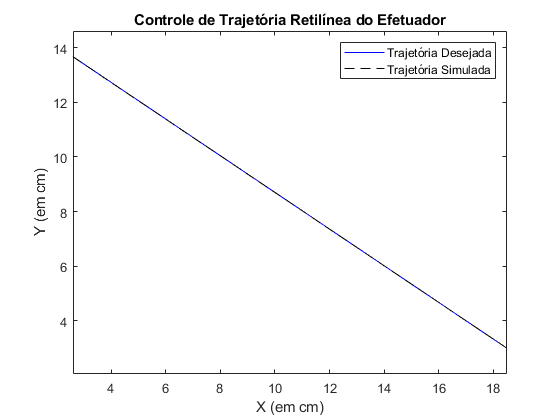

%Trajetória Retilínea
figure,
plot(tx_r,ty_r,'b',X_pot_r(1,:),X_pot_r(2,:),'k--');
ylabel('Y (em cm)'), xlabel('X (em cm)'), title('Controle de Trajetória Retilínea do Efetuador');
legend('Trajetória Desejada','Trajetória Simulada');
axis equal

%********Posições Angulares das Juntas X Tempo*****************************

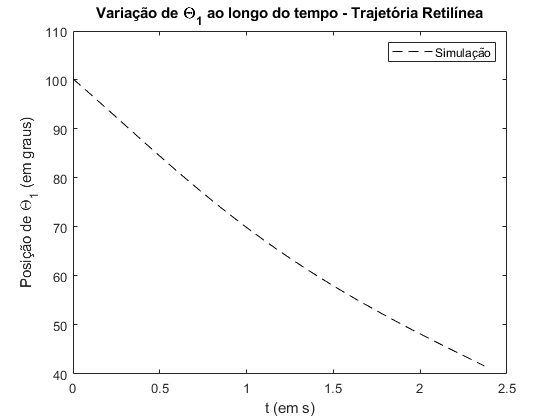

%Trajetória Retilínea
figure,
plot(T_r,q_r(1,:),'k--');
ylabel('Posição de \Theta_1 (em graus)'), xlabel('t (em s)'), title('Variação de \Theta_1 ao longo do tempo - Trajetória Retilínea');
legend('Simulação');

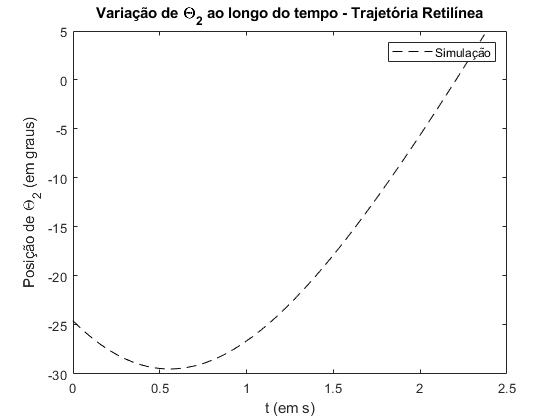

%axis equal;
figure,
plot(T_r,q_r(2,:),'k--');
ylabel('Posição de \Theta_2 (em graus)'), xlabel('t (em s)'), title('Variação de \Theta_2 ao longo do tempo - Trajetória Retilínea');
legend('Simulação');

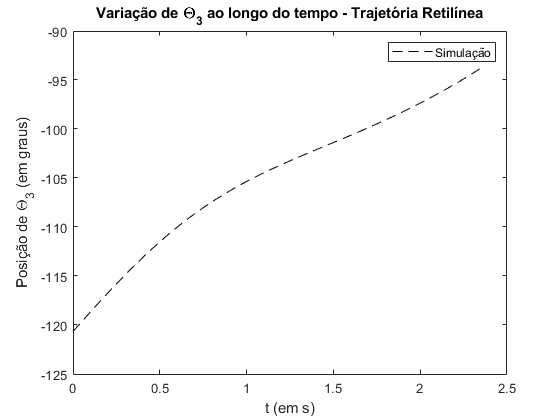

%axis equal;

figure,
plot(T_r,q_r(3,:),'k--');
ylabel('Posição de \Theta_3 (em graus)'), xlabel('t (em s)'), title('Variação de \Theta_3 ao longo do tempo - Trajetória Retilínea');
legend('Simulação');

%axis equal;

%********Erro de Posição X Tempo*******************************************

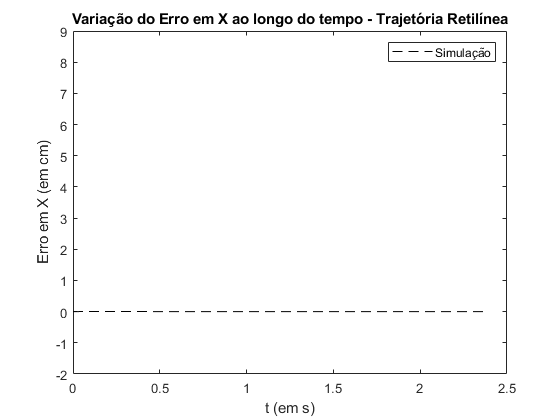

%Trajetória Retilínea
figure,
plot(T_r,e_r(1,:),'k--');
ylabel('Erro em X (em cm)'), xlabel('t (em s)'), title('Variação do Erro em X ao longo do tempo - Trajetória Retilínea');
legend('Simulação');
axis([0,2.5,-2,9]);

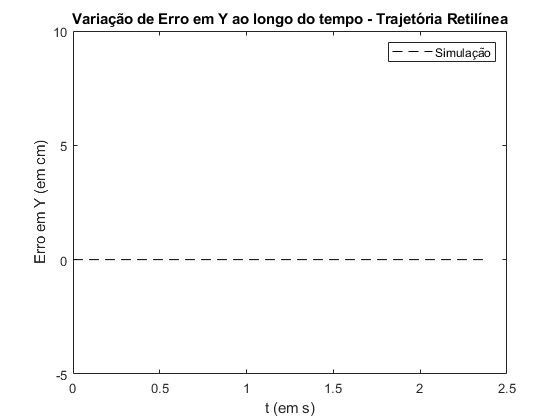

%axis equal;
figure,
plot(T_r,e_r(2,:),'k--');
ylabel('Erro em Y (em cm)'), xlabel('t (em s)'), title('Variação de Erro em Y ao longo do tempo - Trajetória Retilínea');
legend('Simulação');
axis([0,2.5,-5,10]);

%axis equal;

%********Velocidade das Juntas X Tempo*******************************************

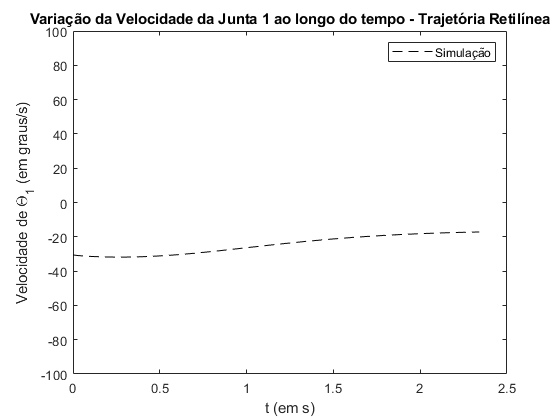

%Trajetória Retilínea
figure,
plot(T_r(1:n_pontos_r-1),dq_r(1,:),'k--');
ylabel('Velocidade de \Theta_1 (em graus/s)'), xlabel('t (em s)'), title('Variação da Velocidade da Junta 1 ao longo do tempo - Trajetória Retilínea');
legend('Simulação');
axis([0,2.5,-100,100]);

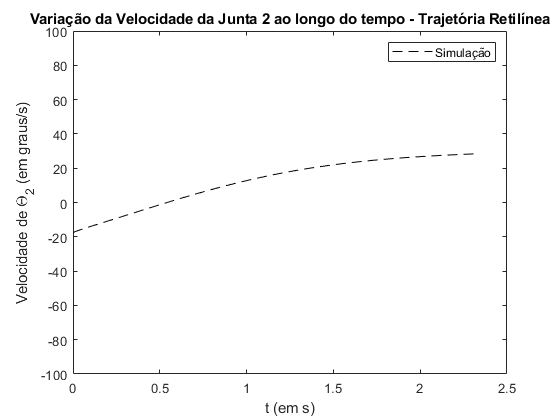

%axis equal;
figure,
plot(T_r(1:n_pontos_r-1),dq_r(2,:),'k--');
ylabel('Velocidade de \Theta_2 (em graus/s)'), xlabel('t (em s)'), title('Variação da Velocidade da Junta 2 ao longo do tempo - Trajetória Retilínea');
legend('Simulação');
axis([0,2.5,-100,100]);

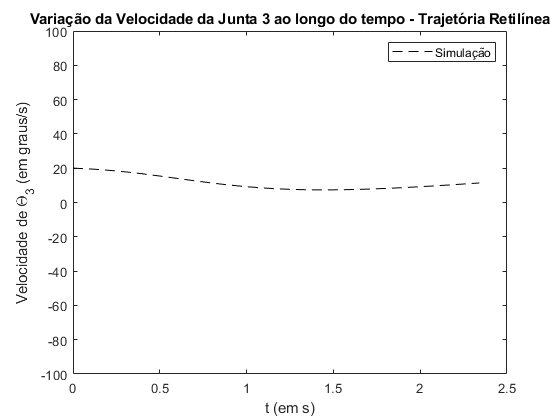

%axis equal;
figure,
plot(T_r(1:n_pontos_r-1),dq_r(3,:),'k--');
ylabel('Velocidade de \Theta_3 (em graus/s)'), xlabel('t (em s)'), title('Variação da Velocidade da Junta 3 ao longo do tempo - Trajetória Retilínea');
legend('Simulação');
axis([0,2.5,-100,100]);

%axis equal;